## Preparació

format compact
clearvars
clc

## Càrrega

% Experiments de Control Automàtic
newData1 = load('-mat', "DadesExperimentalsDinamicaDeSistemes");
vars = fieldnames(newData1);
for i = 1:length(vars)
    assignin('base', vars{i}, newData1.(vars{i}));
end

% Experiments de Control Automàtic
newData1 = load('-mat', "DadesExperimentalsControlAutomatic");
vars = fieldnames(newData1);
for i = 1:length(vars)
    assignin('base', vars{i}, newData1.(vars{i}));
end

% Experiments sobre l'acció D del mòdul PID
newData1 = load('-mat', "DadesExperimentalsSorollAccioD");
vars = fieldnames(newData1);
for i = 1:length(vars)
    assignin('base', vars{i}, newData1.(vars{i}));
end

clearvars newData1 vars i;

## Gràfics Soroll Masses

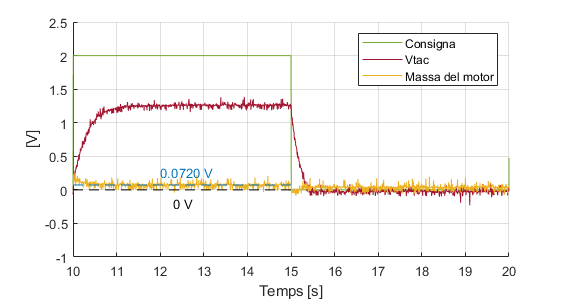

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = 'LlacObertVelocitatPP';
Datapoints = Data_LlacObertVelocitat_GMassaMotor_VRealimentacio;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 20;
Ymin = -1;
Ymax = 2.5;

% Configuració Línia Auxiliar
PrintLine = true;
LineXmin = 10;
LineXmax = 15;
YlineVal = mean(groc((11/0.005):(15/0.005)));
PrintLabel = true;
StringLabel = sprintf('%.4f V', YlineVal);

% Configuració Línia Auxiliar2
PrintLine2 = true;
LineXmin2 = 10;
LineXmax2 = 15;
YlineVal2 = 0;
PrintLabel2 = true;
StringLabel2 = sprintf('%.0f V', YlineVal2);

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
plot(xpoints, groc, 'Color', '#EDB120');

if PrintLine
    %yline(YlineVal, '--', 'Color', '#0072BD');
    plot([LineXmin LineXmax], YlineVal*[1 1], '--', 'Color', '#0072BD');
    if PrintLabel
        text(mean([LineXmin, LineXmax])-0.5, YlineVal+0.2, StringLabel, 'Color', '#0072BD');
    end
end
if PrintLine2
    %yline(YlineVal, '--', 'Color', '#0072BD');
    plot([LineXmin2 LineXmax2], YlineVal2*[1 1], '--', 'Color', 'black');
    if PrintLabel2
        text(mean([LineXmin2, LineXmax2])-0.2, YlineVal2-0.2, StringLabel2, 'Color', 'black');
    end
end

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
legend(["Consigna", "Vtac", "Massa del motor"]);
set(gcf,'units','pixels','position',[0,0,576,384/1.25]);

## Gràfics Alimentació Sèrie Paral·lel

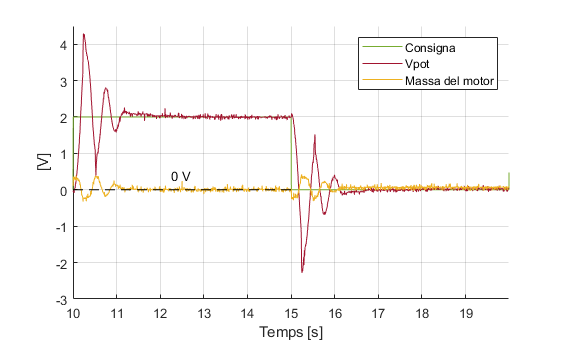

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = '2V Pos - Kp 5 - Ki 10 - AlimParaPP';
Datapoints = Data_PosicioKp5Ki10_GMassaMotor_VRealimentacio_AlimParalel;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 19.995;
Ymin = -3;
Ymax = 4.5;

% Configuració Línia Auxiliar
PrintLine = true;
%LineXmin = 11;
LineXmin = 10;
LineXmax = 15;
%YlineVal = mean(groc((11/0.005):(15/0.005)));
YlineVal = 0;
PrintLabel = true;
%StringLabel = sprintf('%.4f V', YlineVal);
StringLabel = sprintf('%.0f V', YlineVal);

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
plot(xpoints, groc, 'Color', '#EDB120');

if PrintLine
    %yline(YlineVal, '--', 'Color', '#0072BD');
    %plot([LineXmin LineXmax], YlineVal*[1 1], '--', 'Color', '#0072BD');
    plot([LineXmin LineXmax], YlineVal*[1 1], '--', 'Color', 'black');
    if PrintLabel
        %text(mean([LineXmin, LineXmax])-0.5, YlineVal+0.4, StringLabel, 'Color', '#0072BD');
        text(mean([LineXmin, LineXmax])-0.25, YlineVal+0.4, StringLabel, 'Color', 'black');
    end
end

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
legend(["Consigna", "Vpot", "Massa del motor"]);
set(gcf,'units','pixels','position',[0,0,576,384/1.1]);

## Gràfics Càlcul Constants de Temps

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = 'CalculTau';
Datapoints = Data_LlacObertVelocitat_GMassaMotor_VRealimentacio;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 15;
Ymin = 0;
Ymax = 2.5;

% Configuració Línia Auxiliar
YlineVal = mean(vermell((12/0.005):(15/0.005)))

YlineVal = single
1.2578

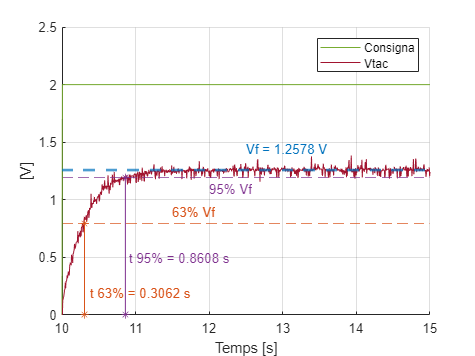

StringLabel = sprintf('Vf = %.4f V', YlineVal);

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
%plot(xpoints, groc, 'Color', '#EDB120');

yline(YlineVal, '--', 'Color', '#0072BD', 'LineWidth', 2);
text(mean([LineXmin, LineXmax])-0.5, YlineVal+0.18, StringLabel, 'Color', '#0072BD');

xpointsp = xpoints((Tmin/0.005):(Tmax/0.005));
p = polyfit(xpointsp, vermell((Tmin/0.005):(Tmax/0.005)), 6);
%vermell2 = polyval(p,xpointsp);
%plot(xpointsp, vermell2); % Veure la regressió polinòmica

YlineVal63 = 0.63*YlineVal;
p63 = p;
p63(end) = p63(end) - YlineVal63;
r63 = roots(p63);
r63 = r63(0 == imag(r63)); % Descartem imaginaris
x63 = r63(r63 < 12); % Ens quedem amb la solucio del règim transitori
yline(YlineVal63, '--', 'Color', '#D95319');
text(11.5, YlineVal63+0.1, '63% Vf', 'Color', '#D95319');
plot(x63*[1 1], [YlineVal63 0], '*-', 'Color', '#D95319');
text(x63+0.07, YlineVal63-0.6, sprintf('t 63%% = %.4f s', (x63-Tmin)), 'Color', '#D95319');

YlineVal95 = 0.95*YlineVal;
p95 = p;
p95(end) = p95(end) - YlineVal95;
r95 = roots(p95);
r95 = r95(0 == imag(r95)); % Descartem imaginaris
x95 = r95(r95 < 12); % Ens quedem amb la solucio del règim transitori
yline(YlineVal95, '--', 'Color', '#7E2F8E');
text(12, YlineVal95-0.1, '95% Vf', 'Color', '#7E2F8E');
plot(x95*[1 1], [YlineVal95 0], '*-', 'Color', '#7E2F8E');
text(x95+0.05, YlineVal95-0.7, sprintf('t 95%% = %.4f s', (x95-Tmin)), 'Color', '#7E2F8E');

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
legend(["Consigna", "Vtac"]);

%legend("Position",[0.6,0.2,0.3,0.15])

## Gràfics Zona morta Kp

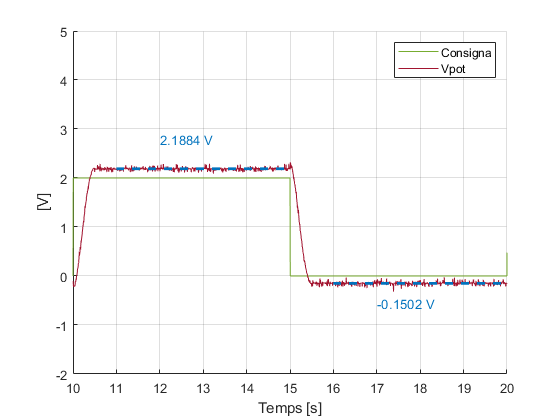

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = '2V Pos - Kp 1 - MiniPP';
Datapoints = Data_PosicioKp1_2V_GMassaMotor_VRealimentacio;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 20;
Ymin = -2;
Ymax = 5;

% Configuració Línia Auxiliar
PrintLine = true;
LineXmin = 11;
LineXmax = 15;
YlineVal = mean(vermell((LineXmin/0.005):(LineXmax/0.005)));
YlineVal2 = mean(vermell(((5+LineXmin)/0.005):((5+LineXmax)/0.005)));
PrintLabel = true;
StringLabel = sprintf('%.4f V', YlineVal);
StringLabel2 = sprintf('%.4f V', YlineVal2);

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
%plot(xpoints, groc, 'Color', '#EDB120');

if PrintLine
    %yline(YlineVal, '--', 'Color', '#0072BD');
    plot([LineXmin LineXmax], YlineVal*[1 1], '--', 'Color', '#0072BD', 'LineWidth', 2);
    plot([LineXmin+5 LineXmax+5], YlineVal2*[1 1], '--', 'Color', '#0072BD', 'LineWidth', 2);
    if PrintLabel
        text(mean([LineXmin, LineXmax])-1, YlineVal+0.6, StringLabel, 'Color', '#0072BD');
        text(mean([5+LineXmin, 5+LineXmax])-1, YlineVal2-0.4, StringLabel2, 'Color', '#0072BD');
    end
end

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
%legend(["Consigna", "Vtac", "Massa del motor"]);
legend(["Consigna", "Vpot"]);

%legend("Position",[0.17,0.28,0.34,0.17]) % Quan es reescala queda bé

## Gràfics Zona morta KpKi

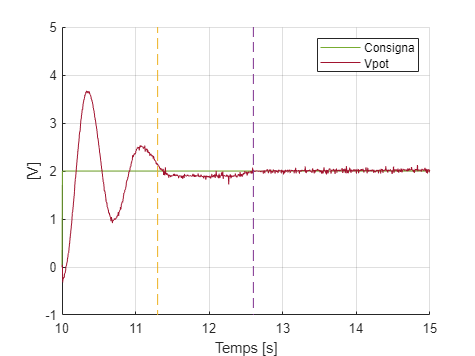

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = '2V Pos - Kp 2 - Ki 9';
Datapoints = Data_PosicioKp2Ki9Kd005_GMassaMotor_VRealimentacio;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);

% Configuració Eixos
Tmin = 10;
Tmax = 15;
Ymin = -1;
Ymax = 5;

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
plot(11.3*[1 1], [-5 5], '--');
plot(12.6*[1 1], [-5 5], '--');

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
%legend(["Consigna", "Vtac", "Massa del motor"]);
legend(["Consigna", "Vpot"]);

%legend("Position",[0.17,0.28,0.34,0.17]) % Quan es reescala queda bé

## Gràfic del Soroll de l'acció D

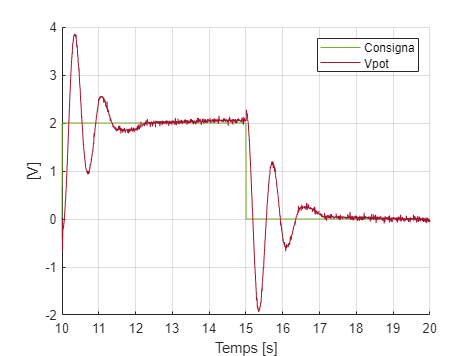

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = '2V Pos - Kp 2 - Ki 10 - Kd 0.07 - F 34Hz - Mini';
Datapoints = Data_PosicioKp2Ki10Kd007Filtre34Hz_2V_VRealimentacio_Gu;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 20;
Ymin = -2;
Ymax = 4;

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
%plot(xpoints, groc, 'Color', '#EDB120');

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
%legend(["Consigna", "Vpot", "Senyal de control"]);
legend(["Consigna", "Vpot"]);

## Gràfic assignació de pols

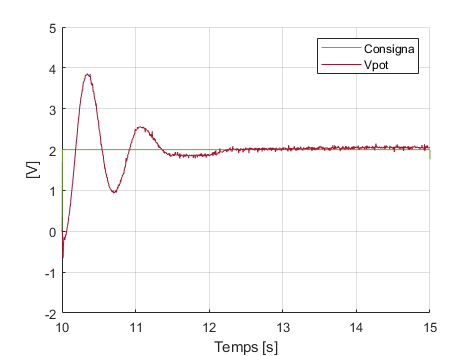

% DS columnes - Consigna, Vermell, Groc, Error teòric
% Configuració Dades
titol = '2V Pos - Kp 2 - Ki 10 - Kd 0.07 - F 34Hz - Uni - Mini';
Datapoints = Data_PosicioKp2Ki10Kd007Filtre34Hz_2V_VRealimentacio_Gu;
consigna = Datapoints(:,1);
vermell = Datapoints(:,2);
groc = Datapoints(:,3);

% Configuració Eixos
Tmin = 10;
Tmax = 15;
Ymin = -2;
Ymax = 5;

% Còmput i 
xpoints = 0.005*(1:size(Datapoints,1));
figure();
hold on;
grid on;

plot(xpoints, consigna, 'Color', '#77AC30');
plot(xpoints, vermell, 'Color', '#A2142F');
%plot(xpoints, groc, 'Color', '#EDB120');

ylabel('[V]');
xlabel('Temps [s]');
axis([Tmin Tmax Ymin Ymax]);
xticks(Tmin:Tmax);
legend(["Consigna", "Vpot"]);

## Guardat

scale = 2

scale = 2

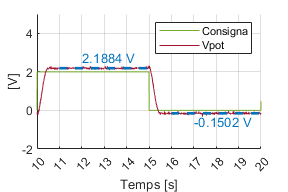

set(gcf,'units','pixels','position',[0,0,576/scale,384/scale]);
exportgraphics(gcf, ['../Resultats experimentals/Generats/', titol, '.png']);
hold off;